3.

%a
f = @(x) x^2-2;
fp = @(x) 2*x;
[~,P]=newtons(f,fp,1,eps,6)

P =    1.000000000000000   1.500000000000000   1.416666666666667   1.414215686274510   1.414213562374690   1.414213562373095   1.414213562373095


[~,D]=secant(f,0,1,eps,100)

D =                    0   2.000000000000000   1.333333333333333   1.400000000000000   1.414634146341463   1.414211438474870   1.414213562057320   1.414213562373095   1.414213562373095   1.414213562373095   1.414213562373095


f = @(x) 0.5*(x-2/x);
err_n=(abs(sqrt(2)-P));
err_s=(abs(sqrt(2)-D));
[~,P]=newtons(f,fp,1,eps,10)

P =    1.000000000000000   1.250000000000000   1.320000000000000   1.356960514233241   1.378501620779506   1.391622579082064   1.399805239248456   1.404978271828720   1.408275704864949   1.410388350736370   1.411746274227810


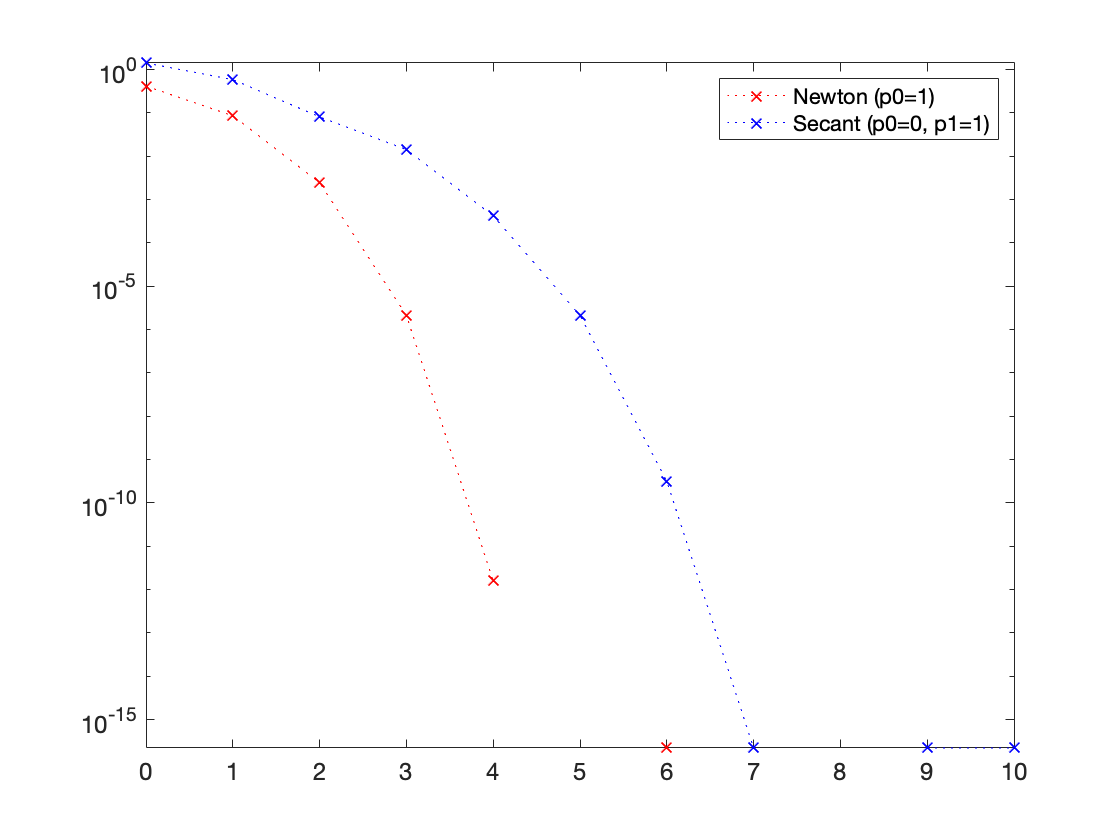

semilogy(0:numel(err_n)-1, err_n, 'rx:', 0:numel(err_s)-1, err_s, 'bx:'); set(gca,'FontSize',12); legend('Newton (p0=1)', 'Secant (p0=0, p1=1)');

%b
f = @(x) tanh(x);
fp = @(x) sech(x)*sech(x);
[~,P]=newtons(f,fp,1.08,eps,100)

P =    1.080000000000000  -1.058953134356348   0.989404207298236  -0.784566773085772   0.363998161109998  -0.033014696137193   0.000023995252668  -0.000000000000009                   0                   0


[~,D]=secant(f,1,1.08,eps,100)

D =    1.000000000000000  -0.927785033049536   0.034152521218739  -0.008848497483988   0.000002548477804  -0.000000000066492   0.000000000000000                   0


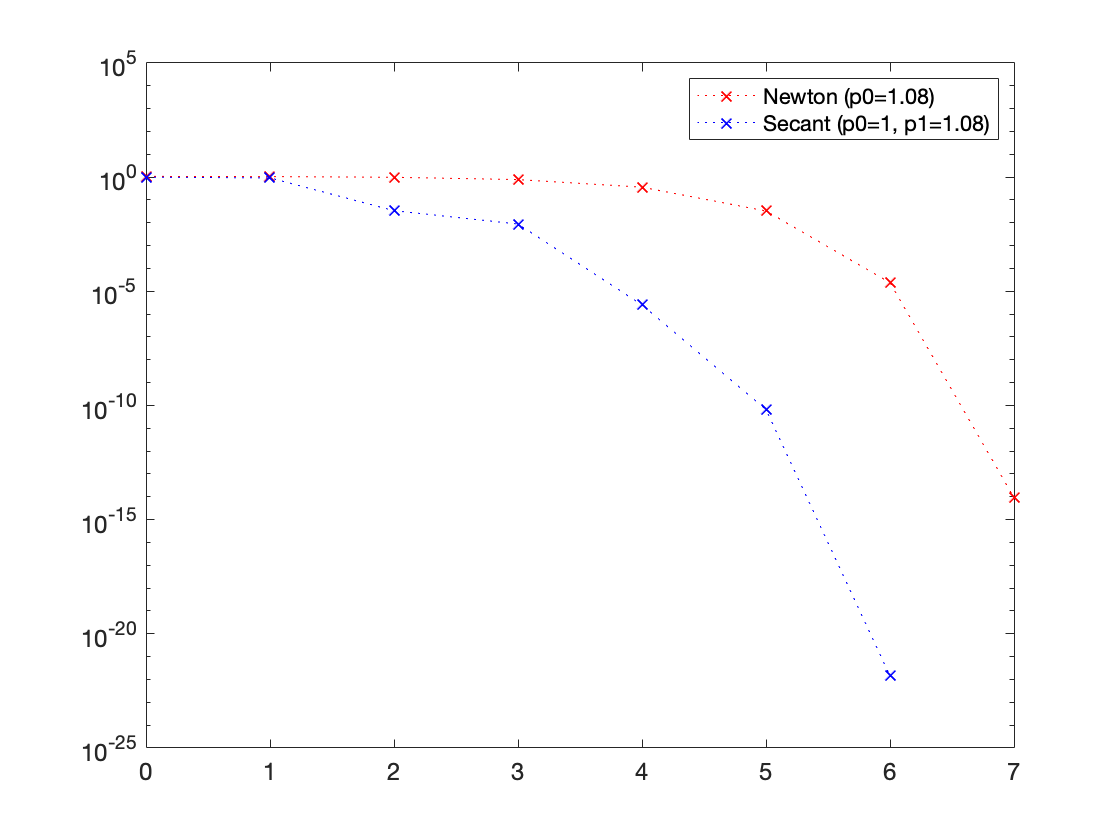

%The derivative of tanh turns 0 when seed value goes beyond 1.0886
err_n=(abs(0-P));
err_s=(abs(0-D));
semilogy(0:numel(err_n)-1, err_n, 'rx:', 0:numel(err_s)-1, err_s, 'bx:'); set(gca,'FontSize',12); legend('Newton (p0=1.08)', 'Secant (p0=1, p1=1.08)');

%c
f = @(x) x^3-2*x+2;
fp = @(x) 3*x^2-2;
[~,P]=newtons(f,fp,-1.7,eps,100)

P =   -1.700000000000000  -1.773013493253373  -1.769302259128211  -1.769292354309085  -1.769292354238631  -1.769292354238631


[~,D]=secant(f,-1.5,-1.7,eps,100)

D =   -1.500000000000000  -1.785588752196837  -1.768458219001016  -1.769282671737078  -1.769292360041262  -1.769292354238591  -1.769292354238631  -1.769292354238631


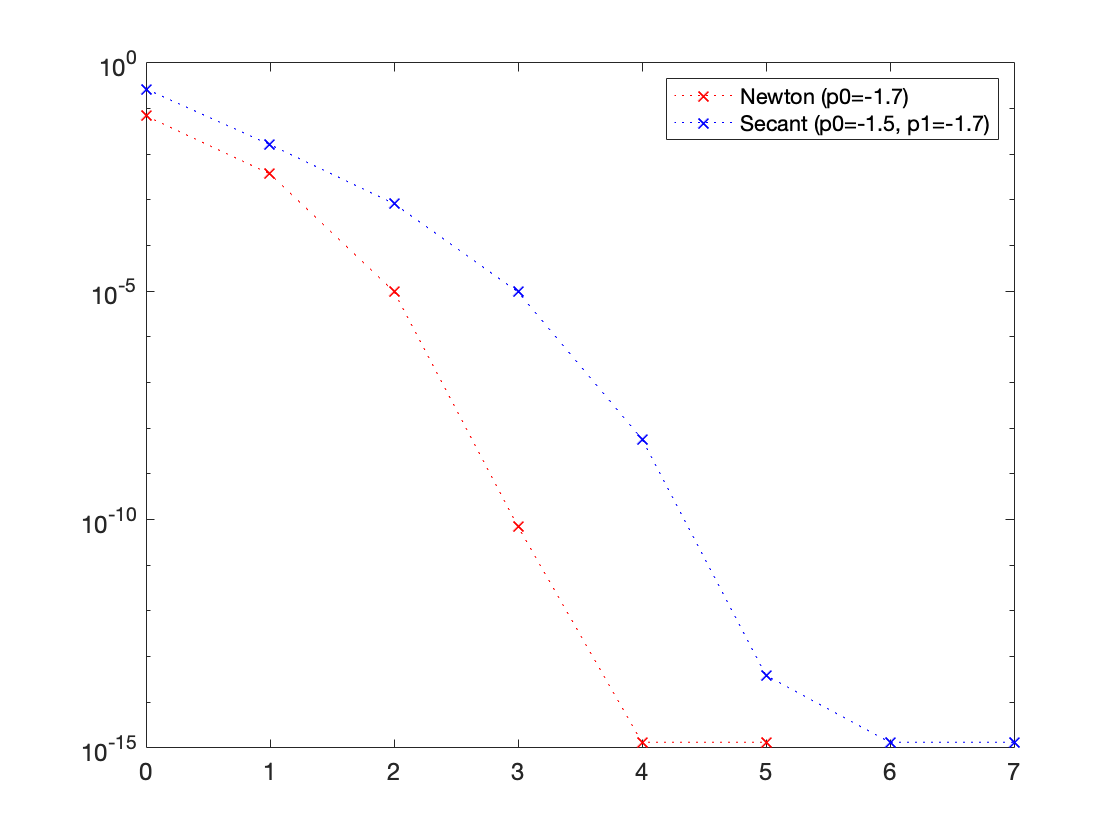

%Newtons method with starting point 1 has a derivative of 0
err_n=(abs(-1.76929235423863-P));
err_s=(abs(-1.76929235423863-D));
semilogy(0:numel(err_n)-1, err_n, 'rx:', 0:numel(err_s)-1, err_s, 'bx:'); set(gca,'FontSize',12); legend('Newton (p0=-1.7)', 'Secant (p0=-1.5, p1=-1.7)');

%d
f = @(x) nthroot(x,3);
fp = @(x) (1/3)*nthroot(x^2,3);
[~,P]=newtons(f,fp,1,eps,100)

P =    1.000000000000000  -2.000000000000000   0.381101577952299  -3.756744572171014  -1.826922072444001   0.627115722669421  -2.877755172172428  -0.768625376518365   2.506412661290101   0.297880492329032  -4.194127983694264  -2.333866353249528  -0.072196233209879   7.132512171216490   5.574011186878047   3.882017872284185   1.973181311861852  -0.418659416847986   3.591555363523744   1.632588606459715  -0.915193799923673   2.174747517633812  -0.140789029914193   5.625967940253714   3.939199356172880   2.039644085300181  -0.325929477447006   4.033336566402635   2.148676189063716  -0.176188052260579   5.175150611874499   3.440759962148294   1.453583370220997  -1.194761911022352   1.632465861980971  -0.915380398394327   2.174350945434266  -0.141326367737345   5.618112713126871   3.930558350353616   2.029612093516131  -0.339852593986942   3.959051189651478   2.062676214455580  -0.294059597349607   4.217321013037594   2.360475803958604   0.107336360654540  -6.205225291409022  -4.57266685042

[~,D]=secant(f,1,1.1,eps,100)

D =    1.000000000000000  -2.097882352222975  -0.327551206152999   1.737951950778127   0.425139440375584  -1.766709440263682  -0.415382662519395   1.763426266250814   0.416474859841546  -1.763789937843379  -0.416353609010402   1.763749516051146   0.416367082608058  -1.763754007190482  -0.416365585557501   1.763753508172891   0.416365751896647  -1.763753563619264  -0.416365733414522   1.763753557458556   0.416365735468092  -1.763753558143080  -0.416365735239918   1.763753558067022   0.416365735265271  -1.763753558075472  -0.416365735262453   1.763753558074532   0.416365735262766  -1.763753558074638  -0.416365735262732   1.763753558074625   0.416365735262735  -1.763753558074626  -0.416365735262735   1.763753558074626   0.416365735262735  -1.763753558074626  -0.416365735262735   1.763753558074626   0.416365735262735  -1.763753558074626  -0.416365735262735   1.763753558074626   0.416365735262735  -1.763753558074626  -0.416365735262735   1.763753558074626   0.416365735262735  -1.76375355807

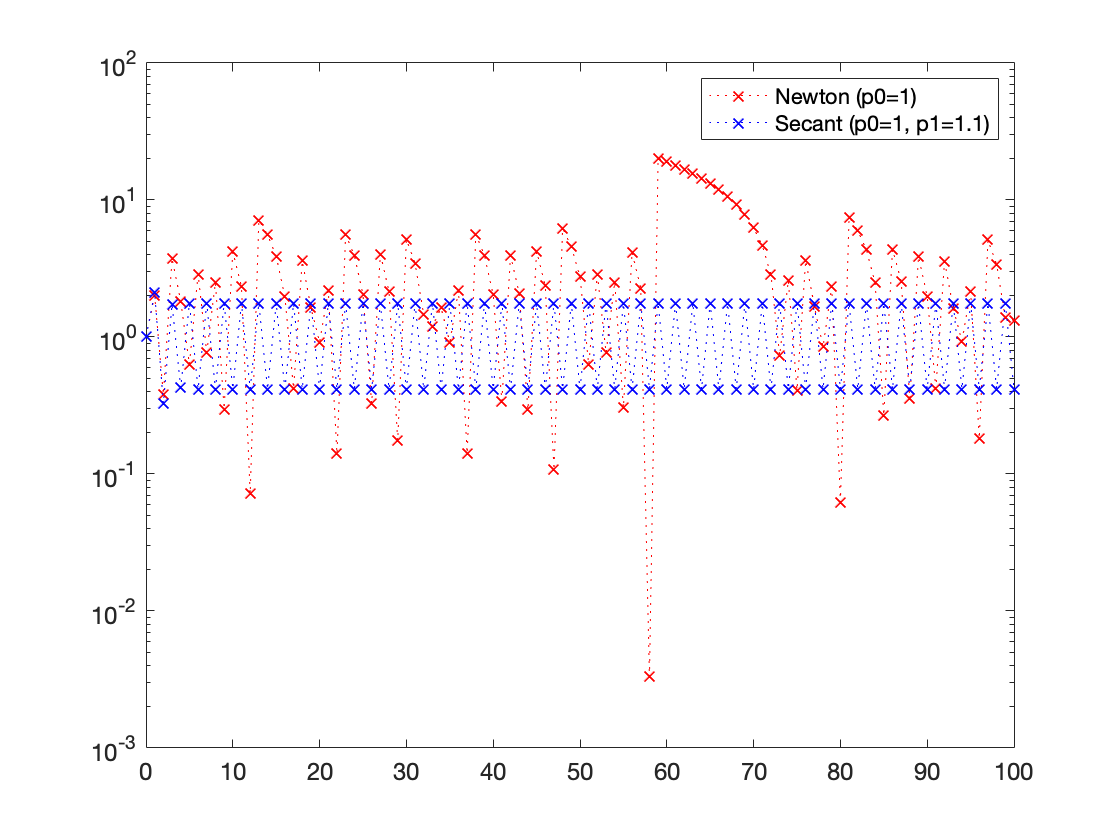

err_n=(abs(0-P));
err_s=(abs(0-D));
semilogy(0:numel(err_n)-1, err_n, 'rx:', 0:numel(err_s)-1, err_s, 'bx:'); set(gca,'FontSize',12); legend('Newton (p0=1)', 'Secant (p0=1, p1=1.1)');

Helper Functions

function [p,P] =newtons(f,fp,p0,tol,maxits)
P=p0;
for i=1:maxits
    p=p0-(f(p0)/fp(p0));
    P=[P,p];
    if (abs(p-p0 )< tol)
        return;
    else
        p0=p;
    end
    
end
end


function [p,P]= secant(f,p0,p1,tol,maxits)
P=p0;
for i=1:maxits
    p=p1-f(p1)*(p1-p0)/(f(p1)-f(p0));
    P=[P,p];
    if (abs(p-p1)<tol)
        return;
    else
        p0=p1;
        p1=p;
        
     end
end
end
